%  Number of Files
numFiles = length(audioFiles);
fixedLength = 16000; % number of samples per file
allWaveforms = [];

%  Loop Through Audio Files
for i = 1:numFiles
    fileName = audioFiles(i);
    
    % Load Audio File
    [y, Fs] = audioread(fileName);
    
    if size(y, 2) > 1
        y = mean(y, 2);
    end
    
    % Resample or Trim to Fixed Length
    if length(y) > fixedLength
        y = y(1:fixedLength); % Trim excess samples
    elseif length(y) < fixedLength
        y = [y; zeros(fixedLength - length(y), 1)]; % Zero-pad if too short
    end
    
    % Normalize Waveform
    y = (y - mean(y)) / std(y);
    
    % Store Processed Waveform
    allWaveforms = [allWaveforms; y'];
end

%  Convert to Numeric Matrix for Autoencoder (Samples × Features)
waveformData = reshape(allWaveforms, numFiles, fixedLength);

disp("Final Waveform Dataset Shape:");

Final Waveform Dataset Shape:


disp(size(waveformData)); % Should be [NumFiles, FixedLength]

          35       16000





%  Define and Train Optimized Autoencoder
hiddenSize = 32; % Increased feature size for better representation

autoenc = trainAutoencoder(waveformData, ...
    hiddenSize, ...
    'MaxEpochs', 200, ... % More epochs for better training
    'L2WeightRegularization', 0.0001, ... % Reduce overfitting
    'SparsityRegularization', 2, ... % Encourage meaningful features
    'SparsityProportion', 0.1, ... % Adjust feature sparsity
    'ScaleData', true);

disp("Optimized Autoencoder Training Complete.");

Optimized Autoencoder Training Complete.


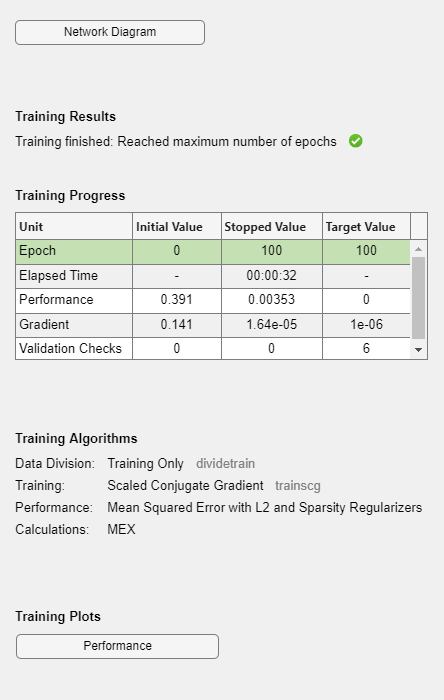

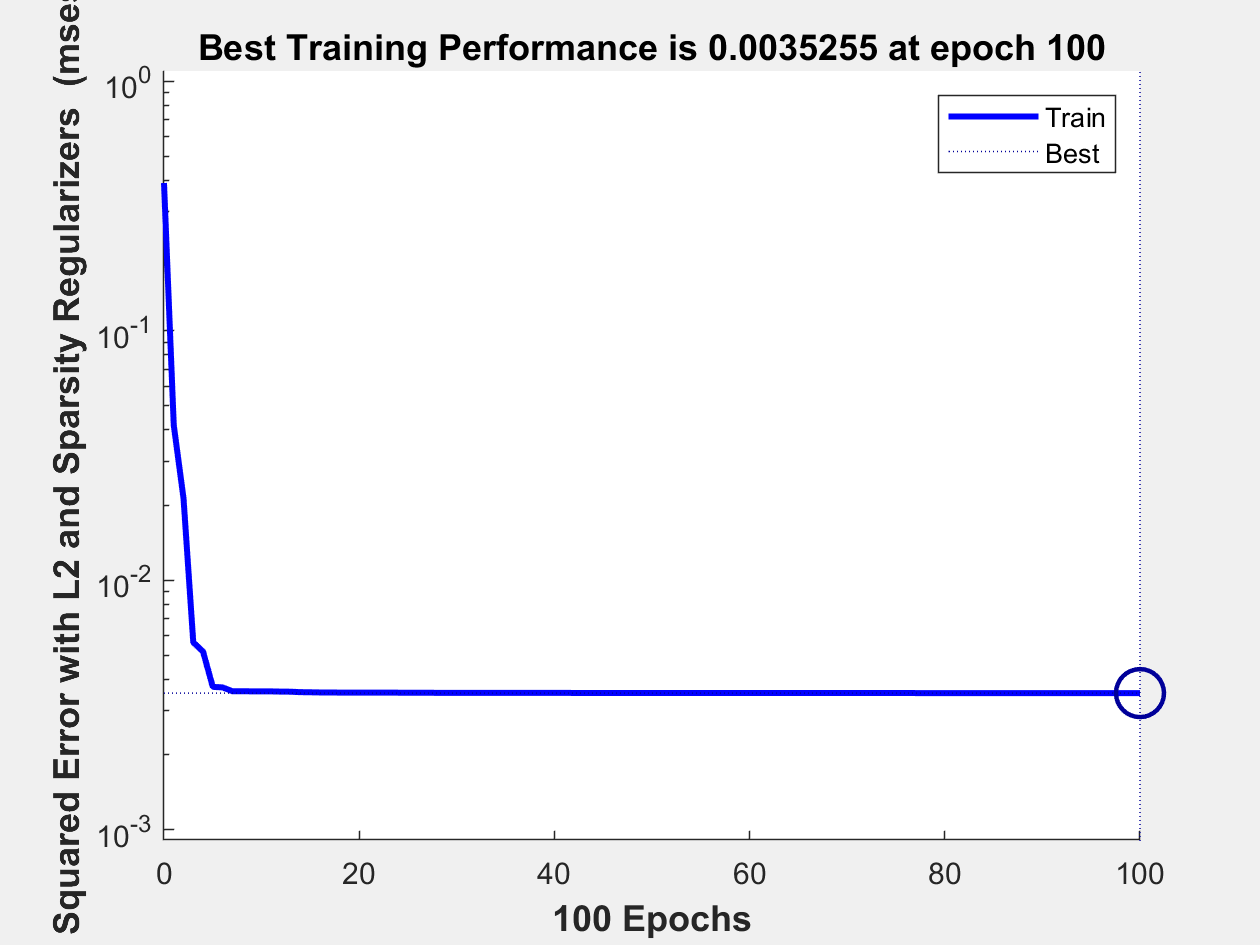

%  Train First Autoencoder
hiddenSize1 = 64; 
autoenc1 = trainAutoencoder(waveformData, hiddenSize1, ...
    'MaxEpochs', 150, ...
    'L2WeightRegularization', 0.0001, ...
    'SparsityRegularization', 1, ...
    'SparsityProportion', 0.1, ...
    'ScaleData', true);

%  Extract Features from First Autoencoder
feat1 = encode(autoenc1, waveformData);

%  Train Second Autoencoder on Encoded Features
hiddenSize2 = 32; % Second layer captures more abstract patterns
autoenc2 = trainAutoencoder(feat1, hiddenSize2, ...
    'MaxEpochs', 100, ...
    'L2WeightRegularization', 0.0001, ...
    'SparsityRegularization', 1, ...
    'SparsityProportion', 0.1, ...
    'ScaleData', true);


%  Extract Final Encoded Features
encodedFeatures = encode(autoenc2, feat1);

disp("Stacked Autoencoder Training Complete.");

Stacked Autoencoder Training Complete.


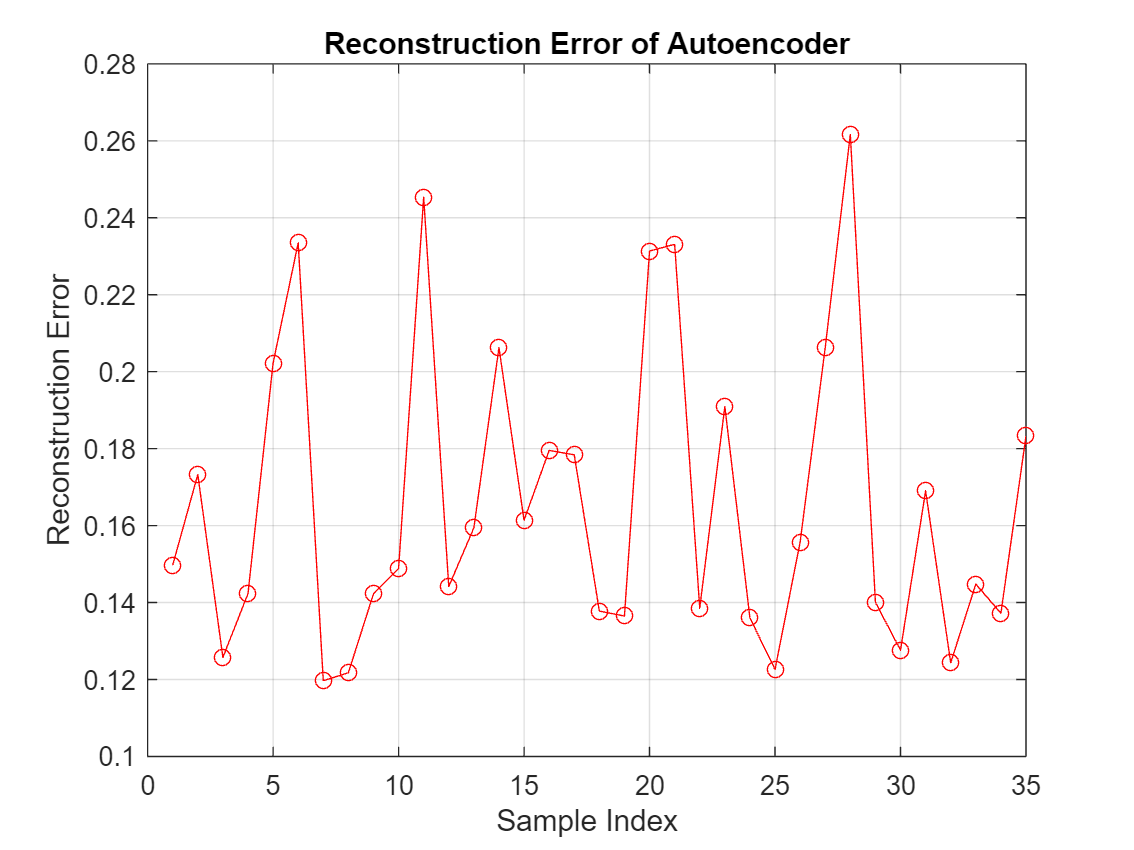

%  Reconstruct Data Using Autoencoder
reconstructedData = predict(autoenc, waveformData);

%  Compute Reconstruction Error
reconstructionError = mean((waveformData - reconstructedData).^2, 2);

figure;
plot(reconstructionError, 'r-o');
xlabel("Sample Index");
ylabel("Reconstruction Error");
title("Reconstruction Error of Autoencoder");
grid on;